# Exercise 8.2 - Spectral analysis of a musical chord

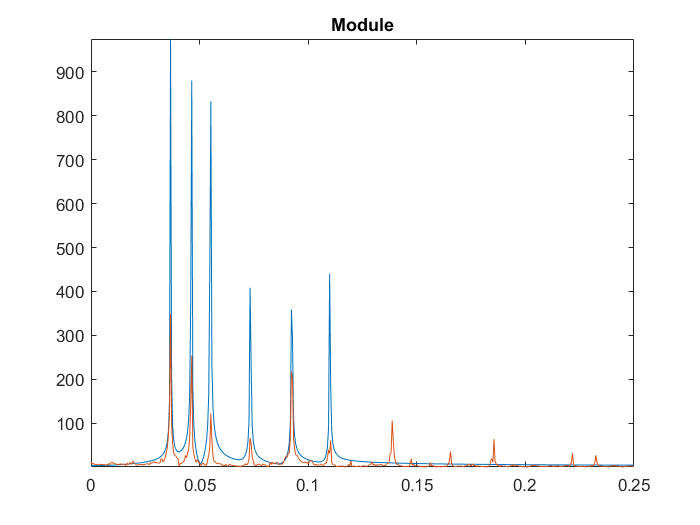

[chord, fs1] = audioread('audio\chord.wav');
N = 2048;       % # of points.

f = (0 : (N - 1)) / N - 0.5;                % OX-axis boundaries.
spectrum = fft(chord / 0.2, N);             % Compute FFT.
spectrumShifted = fftshift(spectrum);       % Shift spectrum to the origin.
plot(f, abs(spectrumShifted)), title('Module');
hold on;

[acordere, fs2] = audioread('audio\acordere.wav');
spectrum2 = fft(acordere, N);               % Compute FFT.
spectrumShifted2 = fftshift(spectrum2);     % Shift spectrum to the origin.
plot(f, abs(spectrumShifted2));
axis([0 0.25 -inf inf]);
hold off;

# Exercise 8.3 - Spectral analysis, windowing

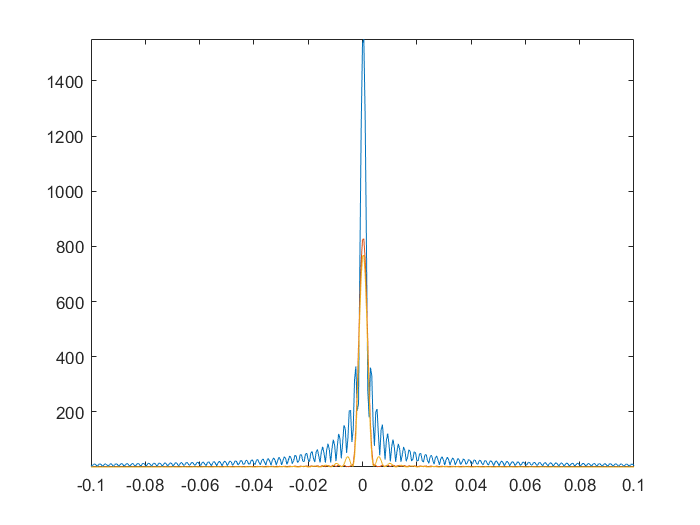

L = 500;    % Window size in samples.
% NOTE: for the rectangular window we simply need to select a set
% of L samples.
chordRectWindow = spectrumShifted(1 : L);          % Rectangular.
chordHamWindow = chordRectWindow .* hamming(L);    % Hamming.
chordTriWindow = chordRectWindow .* triang(L);     % Triangular.

spectrumRect = fft(chordRectWindow, N);                 % Compute FFT.
spectrumShiftedRect = fftshift(spectrumRect);           % Shift spectrum to the origin.

spectrumHam = fft(chordHamWindow, N);
spectrumShiftedHam = fftshift(spectrumHam);

spectrumTri = fft(chordTriWindow, N);                 % Compute FFT.
spectrumShiftedTri = fftshift(spectrumTri);           % Shift spectrum to the origin.

% Represent all windows.
plot(f, abs(spectrumShiftedRect));
hold on;
plot(f, abs(spectrumShiftedHam));
plot(f, abs(spectrumShiftedTri));
axis([-0.1 0.1 -inf inf]);
hold off;

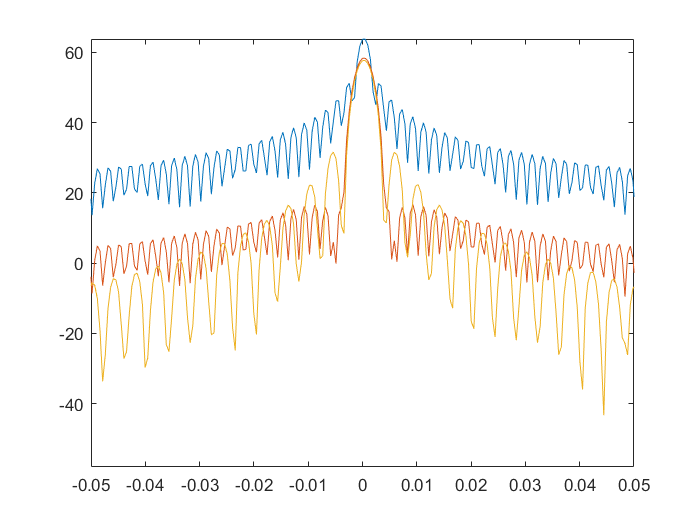


% Comparing secondary lobes.
plot(f, 20 * log10(abs(spectrumShiftedRect)));
hold on;
plot(f, 20 * log10(abs(spectrumShiftedHam)));
plot(f, 20 * log10(abs(spectrumShiftedTri)));
axis([-0.05 0.05 -inf inf]);
hold off;

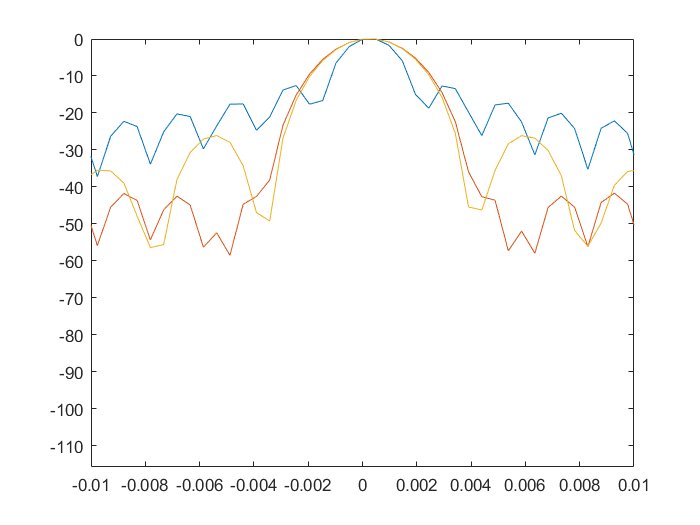


% Comparing the difference between the main and secondary lobe.
plot(f, 20 * log10(abs(spectrumShiftedRect) / max(abs(spectrumShiftedRect))));
hold on;
plot(f, 20 * log10(abs(spectrumShiftedHam) / max(abs(spectrumShiftedHam))));
plot(f, 20 * log10(abs(spectrumShiftedTri) / max(abs(spectrumShiftedTri))));
axis([-0.01 0.01 -inf inf]);
hold off;